# 2018/11/27

## 境界位置検出精度をひと目で分かるようにする．

load("H:/result/2018_11_25_IMCL_estimation_boundary_search_re/2018_11_25_case26/total_result.mat")
load("H:\data\configration\transducer_2board.mat");

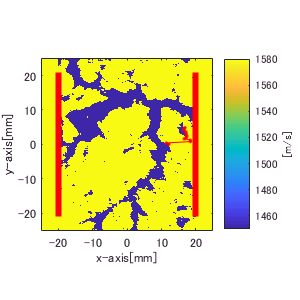

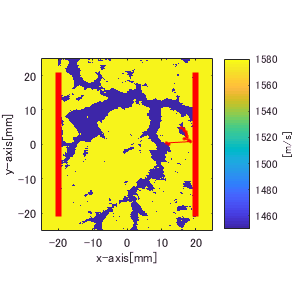

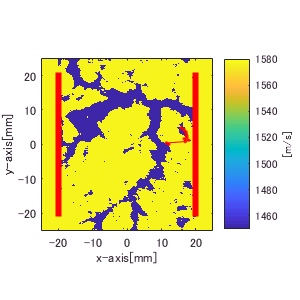

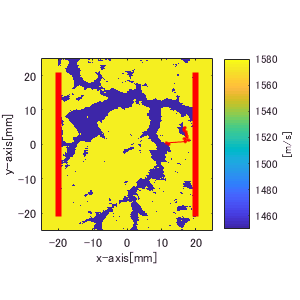

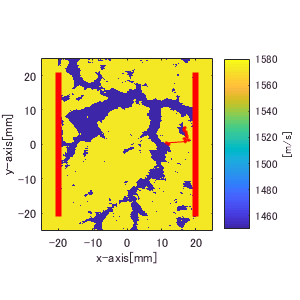

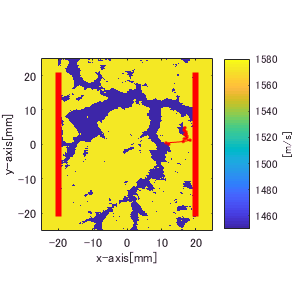

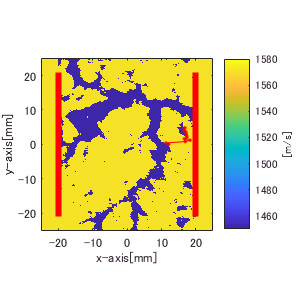

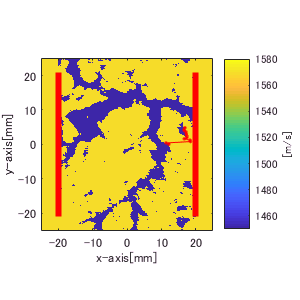

loadpath = sprintf('H:/data/kwave/medium/2018_09_28_realisticScatter_variousIMCL/corrected/');
savepath = sprintf('H:/result/2018_11_25_IMCL_estimation_boundary_search_re/2018_11_25_case26/boundary/whole');
if ~exist(savepath, 'dir')
    mkdir(savepath);
end
for ll = 1:num_medium
    loadfilename = sprintf('case26_IMCL%0.1f_pure.mat',ll);
    load([loadpath, loadfilename]);
    figure;
    imagesc(kgrid.x_vec*1000,kgrid.y_vec*1000,medium.sound_speed);
    hold on
    scatter(t_pos(2,:)*1000,t_pos(1,:)*1000,'rs','filled');
    plot(t_pos(2,1)*1e3 - focal_depth(permute(detected_boundary(ll,ll,:),[3 2 1]))*1e3,...
        single((0:num_lateral-1) * element_pitch)*1e3,'r.-');
    axis equal
    axis tight
    xlabel('x-axis[mm]')
    ylabel('y-axis[mm]')
    caxis([1450 1580]);
    c = colorbar;
    c.Label.String = '[m/s]';
    set(gca,'YDir','normal');
    savefilename = sprintf('/case26_IMCL%0.1f_pure_boundary',ll);
    savefigname = sprintf('/case26_IMCL%0.1f_pure_boundary.fig',ll);
    savefig([savepath,savefigname]);
    exportfig([savepath,savefilename],'png',[300 300]);
end

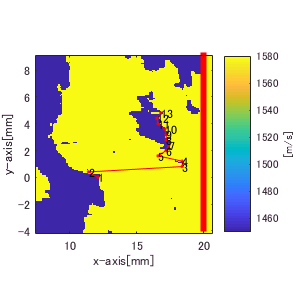

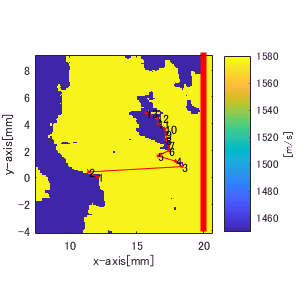

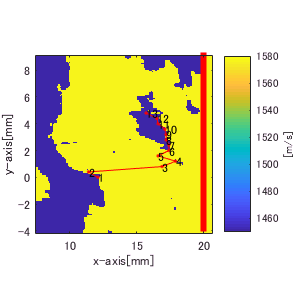

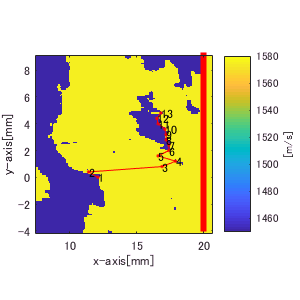

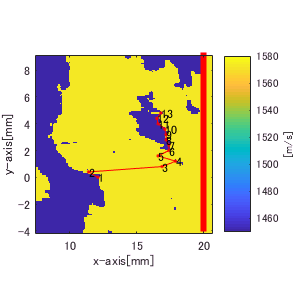

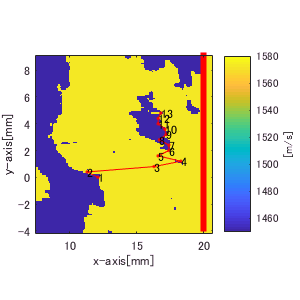

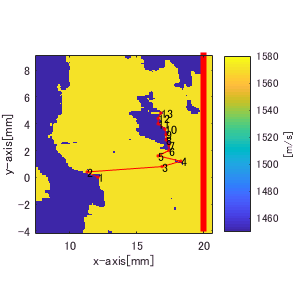

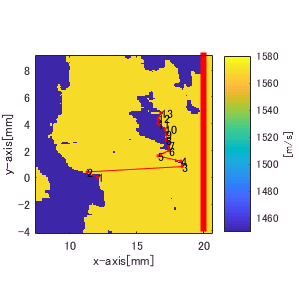

loadpath = sprintf('H:/data/kwave/medium/2018_09_28_realisticScatter_variousIMCL/corrected/');
savepath = sprintf('H:/result/2018_11_25_IMCL_estimation_boundary_search_re/2018_11_25_case26/boundary/detail');
if ~exist(savepath, 'dir')
    mkdir(savepath);
end
for ll = 1:num_medium
    loadfilename = sprintf('case26_IMCL%0.1f_pure.mat',ll);
    load([loadpath, loadfilename]);
    figure;
    imagesc(kgrid.x_vec*1000,kgrid.y_vec*1000,medium.sound_speed);
    hold on
    scatter(t_pos(2,:)*1000,t_pos(1,:)*1000,'rs','filled');
    plot(t_pos(2,1)*1e3 - focal_depth(permute(detected_boundary(ll,ll,:),[3 2 1]))*1e3,...
        single((0:num_lateral-1) * element_pitch)*1e3,'r.-');
    axis equal
    axis tight
    xlabel('x-axis[mm]')
    ylabel('y-axis[mm]')
    caxis([1450 1580]);
    xlim([7.4 20.7])
    ylim([-4.2 9.1])
    c = colorbar;
    c.Label.String = '[m/s]';
    set(gca,'YDir','normal');
%     txtlbl = 1:num_lateral;
%     txtlbl = string(txtlbl);
%     for mm = 1:num_lateral
%     text(t_pos(2,1)*1e3 - focal_depth(permute(detected_boundary(ll,ll,mm),[3 2 1]))*1e3,...
%         double((mm-1) * element_pitch)*1e3,char(txtlbl(mm)));
%     end
    savefilename = sprintf('/case26_IMCL%0.1f_pure_boundary',ll);
    savefigname = sprintf('/case26_IMCL%0.1f_pure_boundary.fig',ll);
    savefig([savepath,savefigname]);
    exportfig([savepath,savefilename],'png',[300 300]);
end